## Load and Explore Image Data

clc;
clear;

rootPath = fullfile('Dataset');

digitDatasetPath = fullfile(rootPath, 'Resized', 'Num');

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

numImageCategories = size(categories(imds.Labels),1);   % get category labels

### Display some of the images in the datastore.

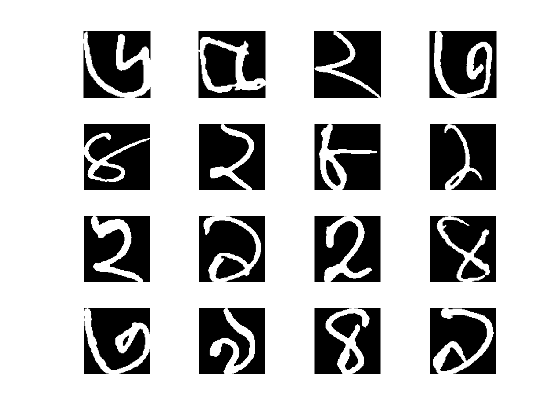

figure;
perm = randperm(20000,16);
for i = 1:16
    subplot(4,4,i);
    imshow(imds.Files{perm(i)});
end

### Count images in each catagory

labelCount = countEachLabel(imds)

labelCount = 10×2 table
    Label    Count
    _____    _____

      0      1982 
      1      1982 
      2      1953 
      3      1975 
      4      1980 
      5      1986 
      6      1981 
      7      1958 
      8      1984 
      9      1967 


#### Check image size

img = readimage(imds, 1);
size(img)

ans =    150   150


### Specify Training and Validation Sets

numTrainFiles = 1500;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## Define Network Architecture

layers = [
    imageInputLayer([150 150 1])
    
    convolution2dLayer(3, 8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(4, 16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2)
    
    convolution2dLayer(2, 32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',1)
    
    convolution2dLayer(5, 64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(numImageCategories)
    softmaxLayer
    classificationLayer
];

## Specify Training Options

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress' ...
);

### Train Network Using Training Data

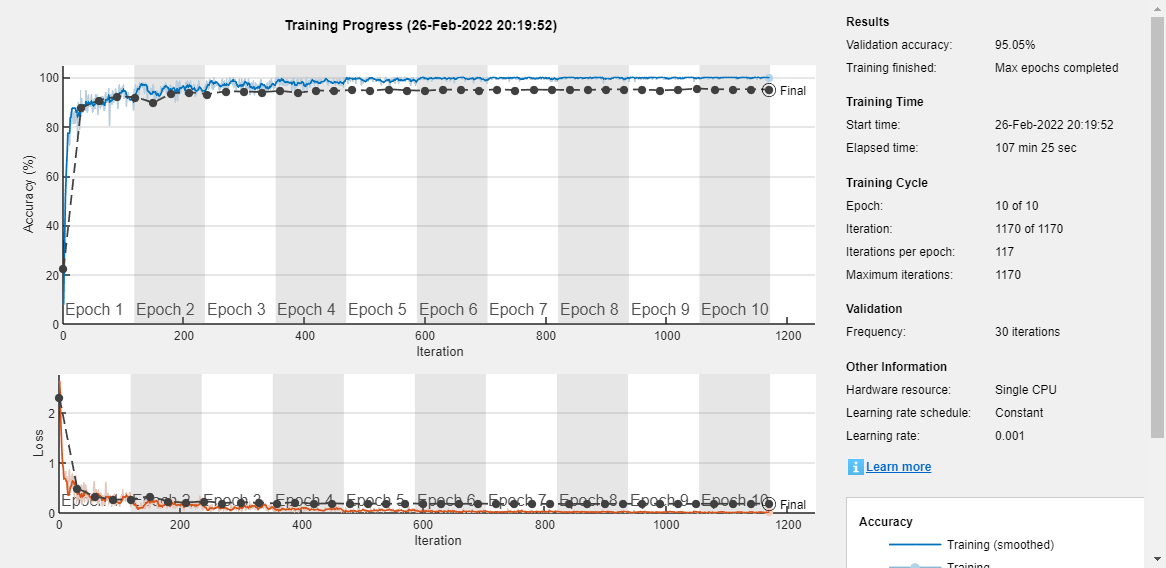

net = trainNetwork(imdsTrain, layers, options);

#### Classify Validation Images and Compute Accuracy

%YPred = classify(net,imdsValidation);
[YPred,probs] = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation);

accuracy = 0.9505

### Display the prediction for Validation Data

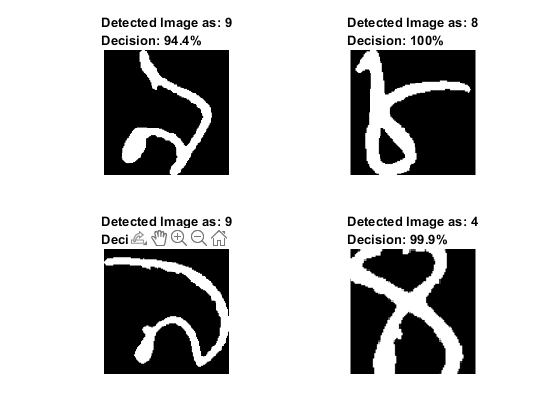

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)

    label = YPred(idx(i));
    percentage = 100*max(probs(idx(i),:));

    title('Detected Image as: ' + string(label) + '\newline' + ...
        'Decision: ' + num2str(percentage,3) + "%");
end

## Take manual images for validation

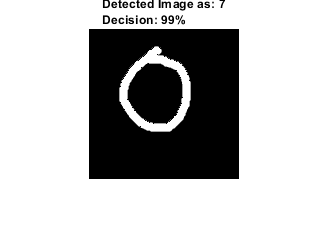

figure

%% Read image from WEBCam
% camera = webcam; % Connect to the camer
% im = snapshot(camera);       % Take a picture
% clear camera;                % Close camera
% im = rgb2gray(im);
% im = im2bw(im, 0.5);         % converting to black & white

%% Read iamge from local storage

im = imread( fullfile(rootPath, 'zTest', 'test.bmp' ));

im = imresize(im,[150 150]); % Resize the picture for alexnet

[label, pro] = classify(net,im);    % Classify the picture
percentage = 100*max(pro);
    
imshow(im);                  % Show the picture

title('Detected Image as: ' + string(label) + '\newline' + ...
'Decision: ' + num2str(percentage,3) + "%");